# Introducing ISET3d calculations

Renders a scene containing a sphere to illustrate the basic read, edit, write cycle.

**See also:**

    t_piIntro_*, piRecipeDefault, @recipe

## Initialize ISET and Docker

Start up ISET and check that docker is configured 

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the recipe

thisR = piRecipeDefault('scene name','sphere');

Read 1 materials.
Read 0 textures.
***Scene parsed.


The recipe has many fields that control the scene properties how it is rendered.  We simply list them here.  A lot of this wiki describes how to set and get properties from the many slots ISET3d recipe slots.

thisR

thisR =   recipe with properties:

            camera: [1×1 struct]
           sampler: [1×1 struct]
              film: [1×1 struct]
            filter: []
        integrator: [1×1 struct]
          renderer: []
            lookAt: [1×1 struct]
             scale: [0×3 double]
             world: {'WorldBegin'}
            lights: []
    transformTimes: []
         inputFile: '/Users/zhenyi/git_repo/dev/iset3d-v4/data/V4/sphere/sphere.pbrt'
        outputFile: '/Users/zhenyi/git_repo/dev/iset3d-v4/local/sphere/sphere.pbrt'
      renderedFile: ''
           version: 4
         materials: [1×1 struct]
          textures: [1×1 struct]
            assets: [1×1 tree]
          exporter: 'C4D'
             media: []
          metadata: [1×1 struct]
         recipeVer: 2
           verbose: 2


## Edit the recipe

For example, we can place a point light in the sphere scene.  Without a light, the scene will appear black!

pointLight = piLightCreate('point','type','point','cameracoordinate', true);
thisR.set('light',pointLight, 'add');

We can also set rendering properties.

thisR.set('film resolution',[192 192]);
thisR.set('rays per pixel',128);
thisR.set('n bounces',1); % Number of bounces
thisR.set('render type', {'radiance', 'depth'});

## Write the recipe, render it, and show it

piWrite(thisR);

In this example, we use a pinhole camera.  Thus, we are rendering the scene radiance.  If we include a lens, we would be rendering an optical image.

[scene, result] = piRender(thisR);

Started Docker with 0: docker run -d -it --name pbrt-cpu-zhenyi19310 -v /Users/zhenyi/git_repo/dev/iset3d-v4/local:/iset/iset3d-v4/local/ camerasimulation/pbrt-v4-cpu-arm:latest bash
Rendered locally in:   2.49
Complete render took: 4.03e+00 seconds.*** Rendering time for sphere:  4.0 sec ***



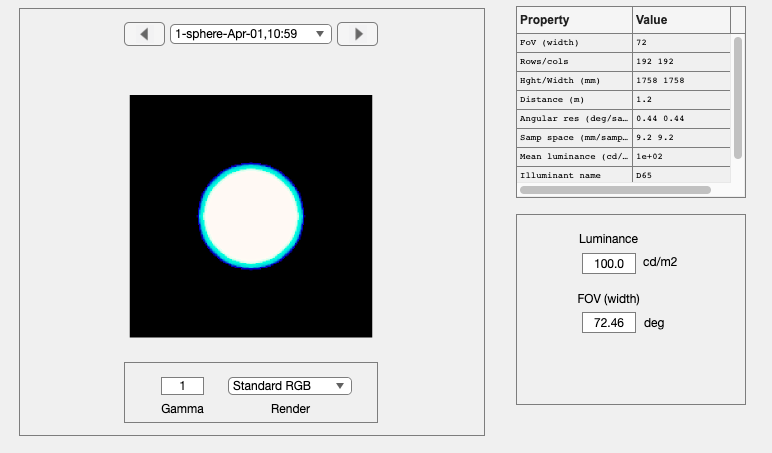

sceneWindow(scene);

## By default, piRender computes the scene or oi depth map

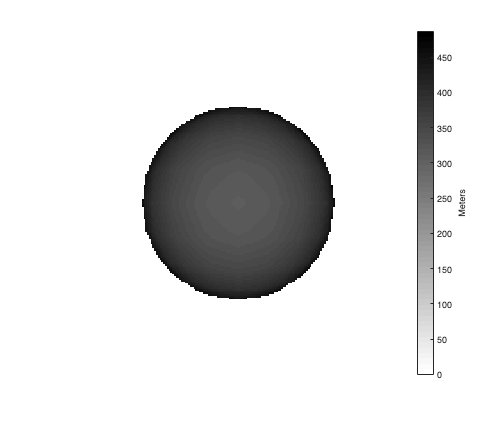

scenePlot(scene,'depth map');

## Change the light to a bluish light

You can edit the lights this way, adding a light which is more blue and distant 

distantLight = piLightCreate('distant','type','distant',  'spd', [9000],  'cameracoordinate', true);
thisR.set('light',pointLight.name, 'delete');
thisR.set('light',distantLight, 'add');

This is an efficient way to Write, Render and Show without the separate calls.

---> Uploading sphere to server...
---> Rendering start...
---> Downloading the files from server...
*** Rendering time for sphere:  7.1 sec ***



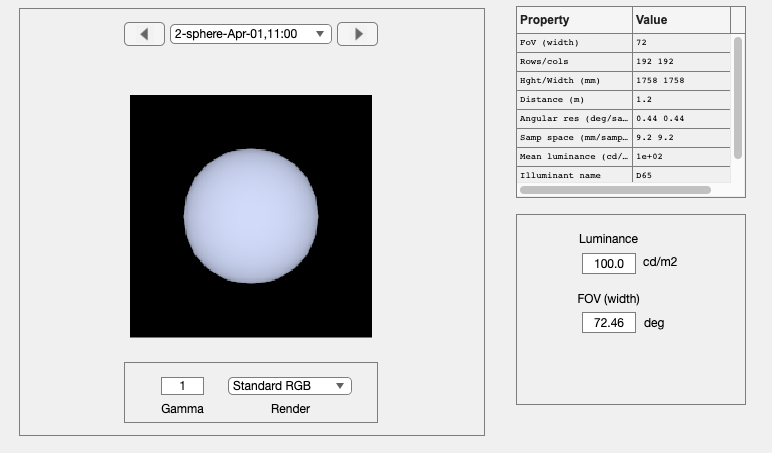

scene = piWRS(thisR);

## Read an  FBX file and write it as PBRT

% FBX is converted into PBRT
fbxFile = fullfile(piRootPath,'data','V4','teapot-set','TeaTime.fbx');
 
thisR  = piRead(fbxFile);

Converting FBX file into PBRT file...
Formating PBRT file...
Copying /Users/zhenyi/git_repo/dev/iset3d-v4/data/V4/teapot-set/TeaTime.fbx
Copying /Users/zhenyi/git_repo/dev/iset3d-v4/data/V4/teapot-set/license.txt
Copied resources from:
/Users/zhenyi/git_repo/dev/iset3d-v4/data/V4/teapot-set 
to 
/Users/zhenyi/git_repo/dev/iset3d-v4/local/formatted/TeaTime-converted 
 
ISET3d-TeaTime-converted-6217


Output argument "blockLine" (and possibly others) not assigned a value in the execution with "piRead>piParseOptions" function.

Error in piRead>piReadLookAt (line 377)
[~, lookAtBlock] = piParseOptions(txtLines,'LookAt');

Error in piRead (line 158)
flip = piReadLookAt(thisR,options);

Convert scene unit from centimeter to meter

thisR.set('film resolution',[600 600]/2);
thisR.set('rays per pixel',32);


Set the render type.

One type is radiance, and here are the others

**rTypes = {'radiance','depth','both','all','coordinates','material','instance', 'illuminant','illuminantonly'};**

thisR.set('film render type',{'radiance','depth'});

%% move object
thisR.set('asset','Cylinder.001_B','world translation',[0.2 0 0]);

thisR.show('objects');

## Add a light

piLightDelete(thisR, 'all'); 
lightName = 'new light';
newLight = piLightCreate(lightName,...
                        'type','infinite',...
                        'spd',[0.4 0.3 0.3],...
                        'specscale',1);
thisR.set('light', newLight, 'add');

% Render and return the scene
scene = piWRS(thisR);

Show the geometry

piAssetGeometry(thisR);view(-80,-65);
